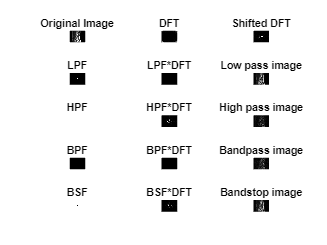

a = imread("spine.jpg");
a = rgb2gray(a);
subplot(531);
imshow(a); title("Original Image");

%Fourier transform
dft = fft2(a);
subplot(532);
imshow(uint16(real(dft)),[]);title("DFT");
shifted = fftshift(dft);
subplot(533);
imshow(uint16(real(shifted)),[]);title("Shifted DFT");

%lowpass 
lpf = frequency(a,40);
subplot(534);
imshow(lpf);title("LPF");
limg = lpf.*shifted;
subplot(535);
imshow(uint16(real(limg)));title("LPF*DFT")
limg = ifft2(fftshift(limg));
subplot(536);
imshow(abs(limg),[]); title("Low pass image");

%highpass
hpf = frequency(a,20);
subplot(537);
imshow(~hpf);title("HPF");
himg = ~hpf.*shifted;
subplot(538);
imshow(uint16(real(himg)));title("HPF*DFT");
himg = ifft2(fftshift(himg));
subplot(539);
imshow(abs(himg),[]);title("High pass image");

%bandpass
bpf = lpf-hpf;
subplot(5,3,10);
imshow(bpf);title("BPF");
bpimg = bpf.*shifted;
subplot(5,3,11);
imshow(uint16(real(bpimg)));title("BPF*DFT");
bpimg = ifft2(fftshift(bpimg));
subplot(5,3,12);
imshow(abs(bpimg),[]);title("Bandpass image");

%bandstop
bsf = ~bpf;
subplot(5,3,13);
imshow(bsf);title("BSF");
bpimg = bsf.*shifted;
subplot(5,3,14);
imshow(uint16(real(bpimg)));title("BSF*DFT");
bpimg = ifft2(fftshift(bpimg));
subplot(5,3,15);
imshow(abs(bpimg),[]);title("Bandstop image");

function y = pixel_dist(x1,y1,x2,y2)
y = sqrt((x1-x2)^2 + (y1-y2)^2);
end

function x = frequency(Img,Do)
[r,c] = size(Img);
x = double(Img);
for i =1:r
    for j = 1:c
        D = pixel_dist(i,j,round(r/2),round(c/2));
        if D<Do
            x(i,j) = 1;
        else
            x(i,j) = 0;
        end
    end
end
end